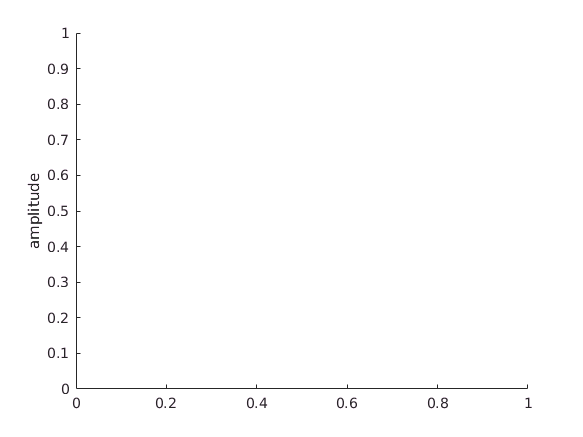

clear variables;
ylabel('amplitude')

[x1,Fe1]= audioread('aaa.wav');

Error using audioread (line 74)
The filename specified was not found in the MATLAB path.


sound(x1,Fe1);
[x2,Fe2]= audioread('chhh.wav');
sound(x2,Fe2);

Te1=1/Fe1;
Te2=1/Fe2;

N1=length(x1);
N2=length(x2);

t1=[0:Te1:(N1-1)*Te1];
t2=[0:Te2:(N2-1)*Te2];

figure(1)
plot(t1,x1)
title('Signal aaa en fonction du temps')
xlabel('temps')
ylabel('amplitude')
plot(t2,x2)
title('Signal chhh en fonction du temps')
xlabel('temps')
ylabel('amplitude')

TF des signaux aaa et chhh

[S1,f1]=TransFourier(x1,t1);
[S2,f2]=TransFourier(x2,t2);

figure(2)
plot(f1,S1)

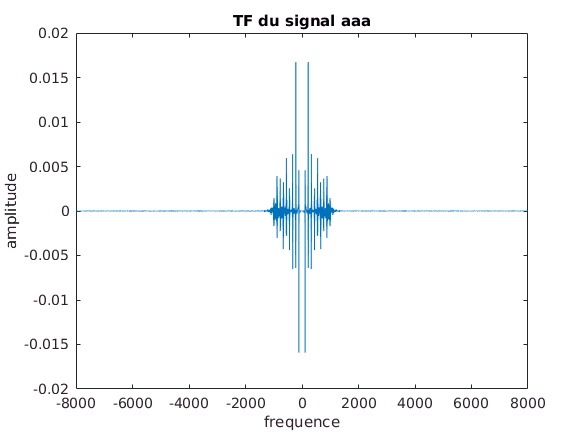

title('TF du signal aaa')
xlabel('frequence')
ylabel('amplitude')

plot(f2,S2)

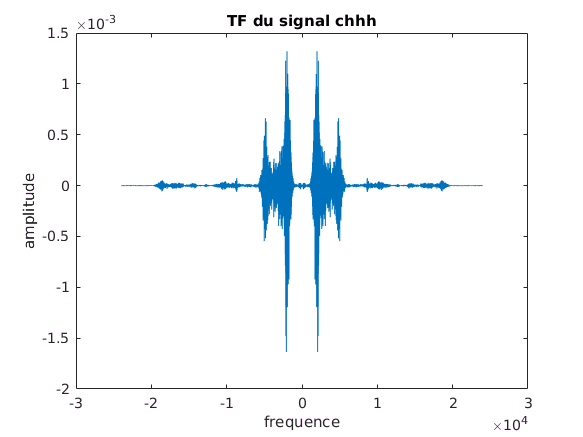

title('TF du signal chhh')
xlabel('frequence')
ylabel('amplitude')

Densité spectrale d'énergie des signaux aaa et chhh

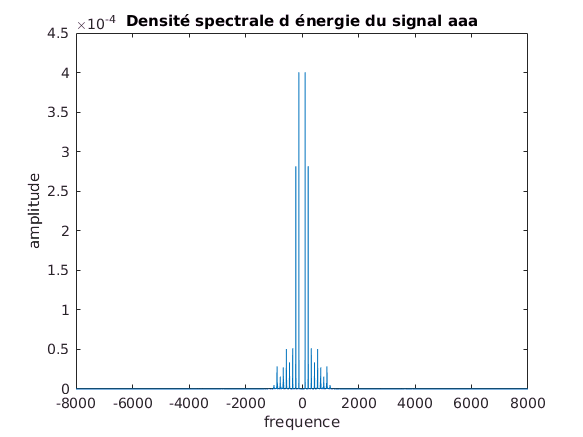

D1=abs(S1).^2;
D2=abs(S2).^2;

figure(3)
plot(f1,D1)
title('Densité spectrale d énergie du signal aaa')
xlabel('frequence')
ylabel('amplitude')

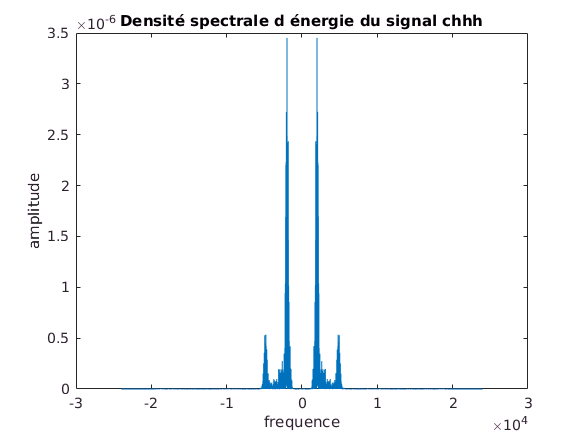

plot(f2,D2)
title('Densité spectrale d énergie du signal chhh')
xlabel('frequence')
ylabel('amplitude')


[m1,i1]=max(D1);
[m2,i2]=max(D2);

D1 est un spectre de raies car le signal aaa est périodique (on voit d'ailleurs bien les oscillations) donc le spectre de sa densité spectrale d'énergie est un spectre ed raies, on peut facilement mesurer les raies.

La dernière raie visible est à environ 1kHz donc la fréquence maximale est 1.1kHz

La fréquence des raies pour D1 est 110Hz (fréquence entre deux raies)

D2 est un spectre standard (on ne voit pas de raies visibles, le signal chhh est difficile à lire)

La fréquence maximale relevée pour D2 est 5.6kHz

FIltre passe-bas

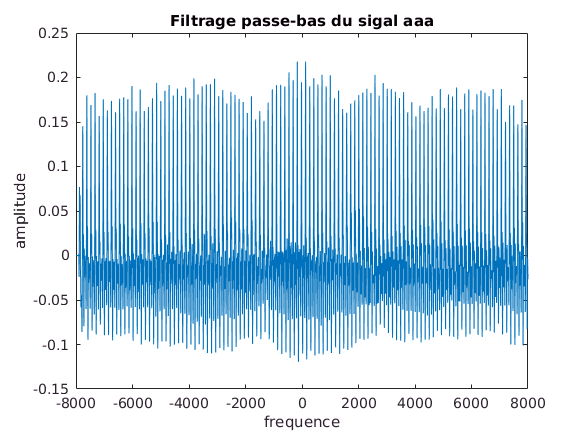

Fc1=613;
Fc2=4000;

sfiltre1=PB(x1,Fe1,Fc1);
sfiltre2=PB(x2,Fe2,Fc2);

figure(4)
plot(f1,sfiltre1)
title('Filtrage passe-bas du sigal aaa')
xlabel('frequence')
ylabel('amplitude')

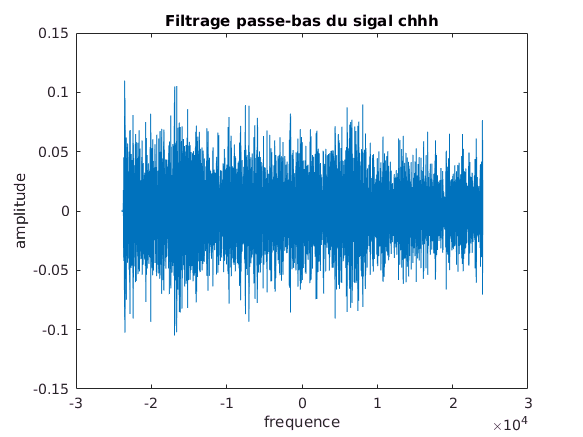

plot(f2,sfiltre2)
title('Filtrage passe-bas du sigal chhh')
xlabel('frequence')
ylabel('amplitude')

Caractérisation du filtre passe-bas

On a choisi Fc1 = 613Hz pour le signal aaa car on veut garder uniquement les 4ères raies (fondamental + 3 harmoniques) et on a pris Fc dans le creux entre la 4ème et 5ème raie

Idem pour Fc2

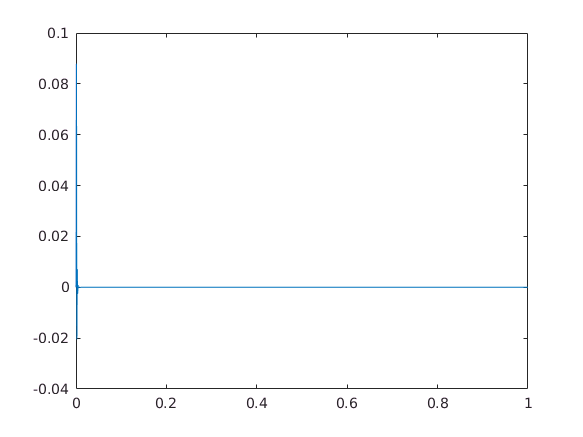

dirac1 = zeros(1,N1);
dirac1(1)=1;
dirac2 = zeros(1,N2);
dirac2(1)=1;
diracfiltre1=PB(dirac1,Fe1,Fc1);
diracfiltre2=PB(dirac2,Fe1,Fc1);

figure(5)
plot(t1,diracfiltre1)

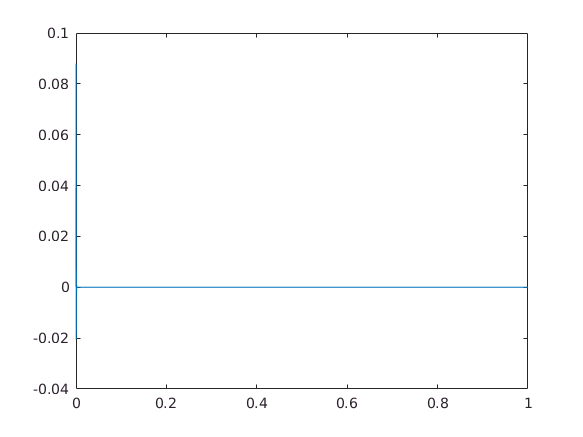

plot(t2,diracfiltre2)

Gain complexe du filtre en module et en phase

figure(6)
plot(f1,20*log(H1))

Undefined function or variable 'H1'.


plot(f1,unwrap(angle(H1)))